# MATLAB TD 3

### Nom Complet: Luiz Felipe SPINOLA SILVA

## Exercice 1 : Image et puzzle

Lire l'image de la bibliothèque matlab 'pout.tif'

Afficher côte à côte l'image et son histogramme, donner une interprétation

Comment faire pour étendre l'histogramme et ainsi augmenter le contraste?

Afficher la nouvelle image (I) avec son histogramme côte à côte.

Détecter les contours de I à l'aide de la méthode "canny". Remplacer les contours détectés, par un pixel blanc dans une copie de l'image initiale. Afficher image initiale, détection de contours et image modifiée côte à côte.

Trouver dans l'aide la commande permettant de faire pivoter I de 90 puis de 180°.

Trouver dans l'aide la commande permettant de translater I de 100 pixels vers le bas et de 50 pixels vers la gauche, en comblant avec du noir

Fabriquer un puzzle de quatre pièces avec cette image : créer 4 images représentant chacune un quart de l'image. Les associer dans le désordre pour créer le puzzle désordonné

Sur une même figure, mettre l'image désordre et l'image I.

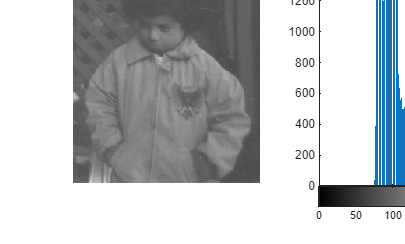

clc; clear; close all;
I = imread('pout.tif');

figure()
subplot(1,2,1)
imshow(I);
title('Original Image');
subplot(1,2,2)
imhist(I);
title('Histogram of Image');

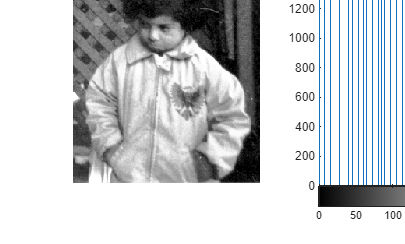

figure()
subplot(1,2,1)
imshow(histeq(I));
title('Histogram of Equalized Image');
subplot(1,2,2)
imhist(histeq(I));
title('Histogram of Equalized Image');

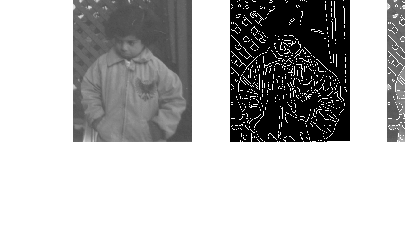

edges = edge(I, 'Canny');
modifiedImage = I;
modifiedImage(edges) = 255;

figure()
subplot(1,3,1)
imshow(I);
title('Original Image');
subplot(1,3,2)
imshow(edges);
title('Detected Edges');
subplot(1,3,3)
imshow(modifiedImage);
title('Modified Image with Edges');

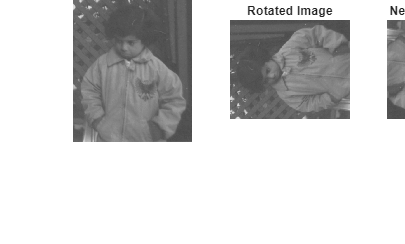

I_rotated = imrotate(I,90);

figure()
subplot(1,3,1)
imshow(I);
title('Original Image');
subplot(1,3,2)
imshow(I_rotated);
title('Rotated Image');
subplot(1,3,3)
imshow(imrotate(I_rotated, 180));
title('New Rotated Image');

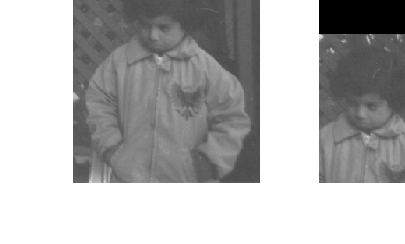

I_translated = imtranslate(I,[-50, 100], 'FillValues',0);

figure()
subplot(1,2,1)
imshow(I);
title('Original Image');
subplot(1,2,2)
imshow(I_translated);
title('Translated Image');

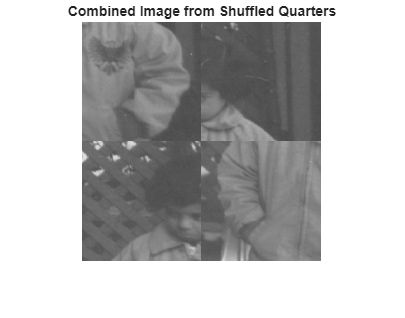

I_original = I;
I = imresize(I, [240 240]);
[lignes, collones] = size(I);
I_quart_1 = imcrop(I, [1 1 (lignes/2) (collones/2)]);
I_quart_2 = imcrop(I, [1 (collones/2) (lignes/2) collones]);
I_quart_3 = imcrop(I, [(lignes/2) 1 lignes (collones/2)]);
I_quart_4 = imcrop(I, [(lignes/2) (collones/2) lignes collones]);

quarters = {I_quart_1, I_quart_2, I_quart_3, I_quart_4};
shuffledQuarters = quarters(randperm(4));

combinedImage = [shuffledQuarters{1}, shuffledQuarters{2}; shuffledQuarters{3}, shuffledQuarters{4}];

figure()
imshow(combinedImage);
title('Combined Image from Shuffled Quarters');

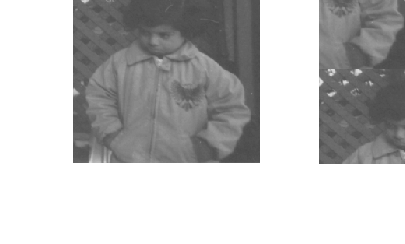

figure()
subplot(1,2,1)
imshow(I);
title('Original Image');
subplot(1,2,2)
imshow(combinedImage);
title('Shuffled Combined Image');

## Exercice 2 : Image et nombres premiers

Récupérer tous les nombres premiers inférieurs à 10000 (cf fonction primes utilisée dans le TD

précédent. Réfléchissez!). Créer et afficher une image 100 par 100, avec un pixel noir si le numéro de l'indice correspondant n'est pas un nombre premier, un pixel blanc si c'est un nombre premier

Mettre des pixels blancs dans toutes les colonnes de 50 à 55

Regarder l'aide de bwselect pour sélectionner manuellement dans un premier temps puis directement

dans le script, la zone blanche recouvrant les colonnes 50 à 55 (+ un ou deux petites structures pour le

fun). Le résultat est une image ne contenant que les structures sélectionnées

Utiliser imshowpair pour comparer l'image initiale et l'image ainsi créée

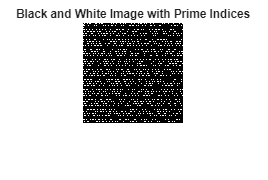

np = primes(10000);

bwImage = false(100, 100);
bwImage(np(:)) = true; 
figure();
imshow(bwImage);
title('Black and White Image with Prime Indices');

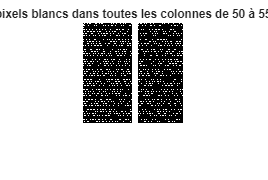

bwImage(:,(50:55)) = true;
figure();
imshow(bwImage);
title('pixels blancs dans toutes les colonnes de 50 à 55')

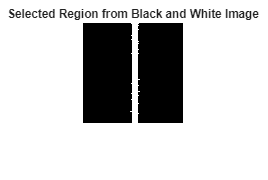

imbw2 = bwImage(:,(50:55));
c = [1 50 55];
r = [1 50 73];
imbw3 = bwselect(bwImage, c, r);

% Display the selected region from the black and white image
figure();
imshow(imbw3);
title('Selected Region from Black and White Image');

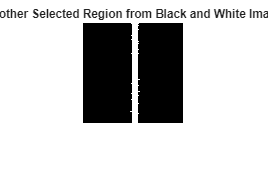

c = [1 55 64];
r = [1 61 70];
imbw4 = bwselect(bwImage, c, r);
% Display the selected region from the black and white image
figure();
imshow(imbw4);
title('Another Selected Region from Black and White Image');

## Exercice 3 : Image et binarisation

Lire et afficher l'image scanner du foie du fichier 'im_scanner.png'

Quelles informations sur l'image pouvez-vous tirer du workspace ?

Transformer cette image en niveaux de gris

Afficher son histogramme. Binariser cette image en jouant sur le seuil pour isoler le foie

Lire et afficher l'image segmentée du foie du fichier 'im_segmente.png'

Sur cette image, le foie apparaît en vert. Modifiez cette image pour le faire apparaître en rouge

uniquement.

Grâce à cette image, mettre en évidence le foie sur l'image initiale en le coloriant en rouge

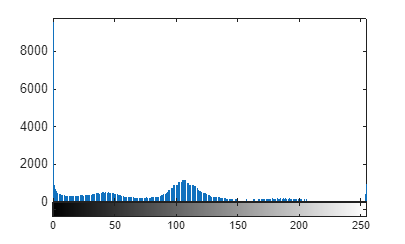

J = imread("images\im_scanner.png");
% Ans: l'image est rgb

J = rgb2gray(J);

figure();
imhist(J);

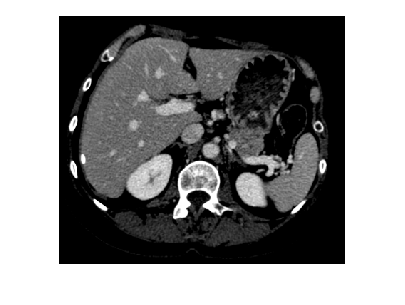

figure();
imshow(J)

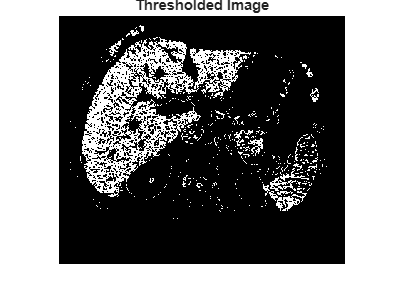

%%
%if J value is between 100 and 200, its value turns into 255, otherwise it
%becomes zero
J(J < 100 | J > 120) = 0;
J(J >= 100 & J <= 120) = 255; 
figure();
imshow(J);
title('Thresholded Image');

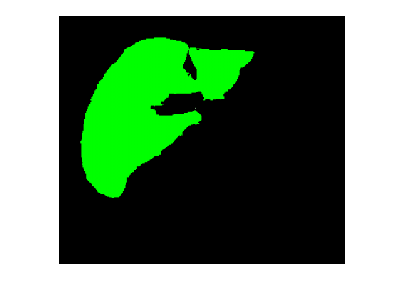

J_segmented = imread("images\im_segmente.png");
figure();
imshow(J_segmented);